# Exercise 3 - Noise Filtering

## 1 - White Gaussian Noise

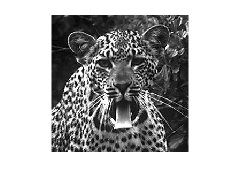


storedStruct = load("/home/sotosgeo/Desktop/digitalImageProc/dgp-2022/Exercises/Ex3/tiger.mat");
tiger = storedStruct.tiger;
imshow(tiger,[]);

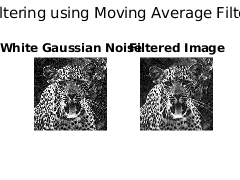



% Get size of image
[rows,columns,noOfColorChannels] = size(tiger);

% Adding white Gaussian noise such that SNR = 15 dB.
%Noise Formula
%dNoise = d + sqrt(10^(SNR/10)) * randomPixels = variance * randomPixels
%SNR = Psignal/Pnoise, for Psignal I use the mean intensity of the image.
SNR = 15;

Psignal = sum(sum(tiger(:,:).^ 2)) / (rows * columns);

%Calculating noise variance
variance = sqrt(Psignal / 10 ^(SNR/10));

%Additive White Gaussian Noise calculation and adding to signal
AWGN(:,:) = variance * randn(rows,columns);
noisyTiger = tiger + AWGN;

[PSNR, actualSNR] = psnr(noisyTiger,tiger);

%imshowpair(tiger,noisyTiger,'montage');

%Filtering AWGN using Moving Average Filter
%Creating a MAF using fspecial and one using filter
windowSize = 3;
MAF_kernel = ones(windowSize,1)/windowSize;
MAF = fspecial('average',windowSize);

MAF_filtered_matlab = imfilter(noisyTiger,MAF);
MAF_filtered = filter(MAF_kernel,1,noisyTiger);

f2 = figure;
subplot(1,2,1)
imshow(noisyTiger);
title('White Gaussian Noise');
subplot(1,2,2);
imshow(MAF_filtered);
title('Filtered Image');
sgtitle('Filtering using Moving Average Filter');

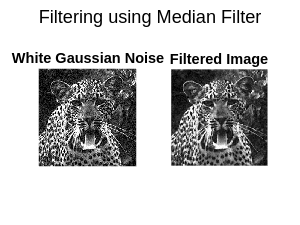



%Filtering AWGN using Median Filter
f3 = figure;
Median_Filtered = medfilt2(noisyTiger);
subplot(1,2,1)
imshow(noisyTiger);
title('White Gaussian Noise');
subplot(1,2,2);
imshow(Median_Filtered);
title('Filtered Image');
sgtitle('Filtering using Median Filter');

## 2 Kroustikos Noise

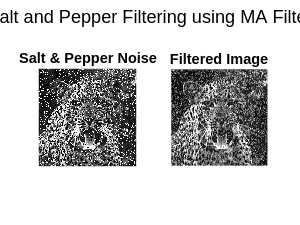

p = 0.2; %20 percent of pixels altered

noisyTiger2 = imnoise(tiger,'salt & pepper',0.2);

% Filter using MAF
MAF_filtered2 = filter(MAF_kernel,1,noisyTiger2);

%Filter using Median Filter
Median_Filtered2 = medfilt2(noisyTiger2);

f4 = figure;
subplot(1,2,1)
imshow(noisyTiger2);
title('Salt & Pepper Noise');
subplot(1,2,2);
imshow(MAF_filtered2);
title('Filtered Image');
sgtitle('Salt and Pepper Filtering using MA Filter');

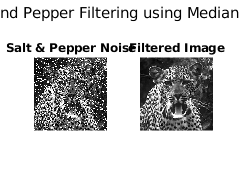



f5 = figure;
subplot(1,2,1)
imshow(noisyTiger2);
title('Salt & Pepper Noise');
subplot(1,2,2);
imshow(Median_Filtered2);
title('Filtered Image');
sgtitle('Salt and Pepper Filtering using Median Filter');

## 3 - Both Noises

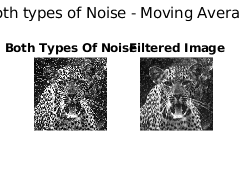

BothNoises = (noisyTiger + noisyTiger2) / 2;


%Using Moving Average Filter First
MAF_first = filter(MAF_kernel,1,BothNoises);
MAF_then_Median = medfilt2(MAF_first);

%Using Median Filter First
Median_first = medfilt2(BothNoises);
Median_then_MAF = filter(MAF_kernel,1,Median_first);


f6 = figure;
subplot(1,2,1)
imshow(BothNoises);
title('Both Types Of Noise');
subplot(1,2,2);
imshow(MAF_then_Median);
title('Filtered Image');


sgtitle("Removing both types of Noise - Moving Average Filter first");

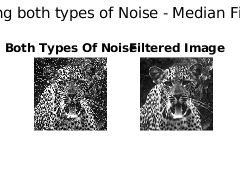



f7 = figure;
subplot(1,2,1)
imshow(BothNoises);
title('Both Types Of Noise');
subplot(1,2,2);
imshow(Median_then_MAF);
title('Filtered Image');

sgtitle("Removing both types of Noise - Median Filter first");

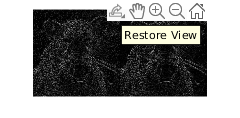



%Checking which order of filtering is best by finding out the sum of
%absolute differences between the filtered images and the original one
f8 = figure;
imshow([imabsdiff(tiger,MAF_then_Median) imabsdiff(tiger,Median_then_MAF)]);


%The median filter is better to apply first, inorder to remove S&P noise,
%because applying a moving average filter to an S&P noisy image, will add
%the high intensity values of salt and peppered pixels to nearby clean
%ones - for report




